% Initialiser
clear; clc;

% Gitt transferfunksjon
numerator = 500; % Telleren
denominator = [1 105 500 0]; % Nevneren: s^3 + 105s^2 + 500s

% Opprett transferfunksjonen i MATLAB
H = tf(numerator, denominator);

% Finn polene
poles = pole(H);
fprintf('Systemets poler:\n');

Systemets poler:


disp(poles);

     0
  -100
    -5




% Beregn knekkfrekvensene (absoluttverdi av polene)
break_frequencies = abs(poles);
fprintf('Knekkfrekvenser (rad/s):\n');

Knekkfrekvenser (rad/s):


disp(break_frequencies);

     0
   100
     5



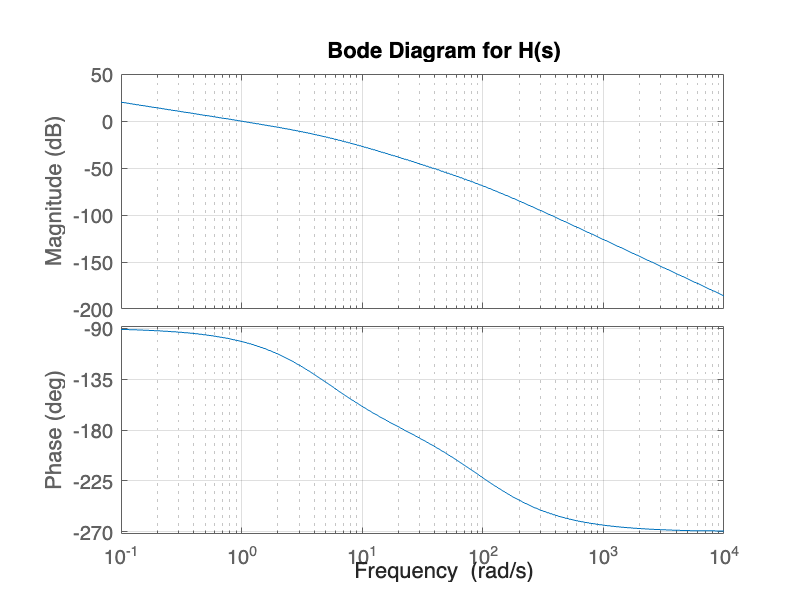


% Tegn asymptotisk Bode-diagram
figure;
bode(H);
grid on;
title('Bode Diagram for H(s)');